# **Matlab homework (lab 2)**

 clear; close all;


% ALSO : Do not use make additional calls to "clear all;" between steps.

%% load file from .mat
load datafile.mat % you can edit here if your datafile has a different name, but do not add path to the file (otherwise it does not work on a different computer)

%%Data set con 742 observaciones (n)
%%X1 indica el ruido (loudness) de cada cancion en decibelios 
% (rango entre -60 y 0 db)
%%X2 indica el tempo, o velocidad de la cancion, en beats per 
% minute o BPM
%%Y indica la popularidad de cada cancion de cada album del 
% grupo de rock The Cure, la puntuacion va del 0 al 100, 
% siendo mas popular a mas puntuacion reciba (la popularidad 
% de cada cancion fue determinada mediante Spotify for 
% Developers, que permite realizar estudios a partir de los 
% datos recogidos por la plataforma de Spotify)

%%El objetivo es mostar que nuestro regresor Y, que 
% representa la popularidad, tiene relacion con los 
% regresores ruido X1 y tempo X2

# QUESTION 2

% Enter code for question 2 here

% Primero indicamos el tamaño de las muestras y luego la K
% que usamos para el caso de estudio de variables
N = length(DATA);
K = 2;
% Definimos la matriz X
Xmatriz=ones(N,3);
Xmatriz(:,2)=DATA(:,1);
x1 = DATA(:,1);
Xmatriz(:,3)=DATA(:,2);
x2 = DATA(:,2);
% Vector Y
Yreal = DATA(:,3);
% Calculamos los coeficientes B con la formula vista en teoria
% Inversa de la multiplicacion de Xt y X
p = inv((transpose(Xmatriz)*Xmatriz));
% los coeficientes B se calculaban con la transpuesta de la 
% matriz inversa multiplicada con el regresor Y
Bmostral = p*transpose(Xmatriz) * Yreal;
disp("Bmostral: " + Bmostral);

    "Bmostral: 7.809"
    "Bmostral: -2.2715"
    "Bmostral: 0.027582"



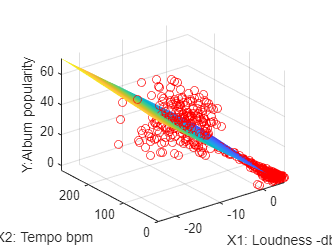

% La representacion de las predicciones resulta en un plano
% Para dibujar el plano resultante indicamos unas 
% restricciones para los X1 y X2
X1=min(x1):(max(x1)-min(x1))/N:max(x1);
X2=min(x2):(max(x2)-min(x2))/N:max(x2);
[X1meshed,X2meshed]=meshgrid(X1,X2);
% Ahora lo calculamos
zplane = Bmostral(1,1) + Bmostral(2,1)*X1meshed + Bmostral(3,1)*X2meshed; 
%Y para representarlo
h = surf(X1meshed,X2meshed,zplane);hold on;
set(h,'LineStyle','none');
scatter3(x1,x2,Yreal, 'red');
xlabel('X1: Loudness -db');
ylabel('X2: Tempo bpm');
zlabel('Y: Album popularity');

figure();

# QUESTION 3

% write your code here code

%Calculamos la y con sombrero y luego todos los valores de 
% la tabla ANOVA para asi calcular el F estadistico
YR= Xmatriz*Bmostral;
SSREG = transpose(Bmostral)*transpose(Xmatriz)*Yreal-power(sum(Yreal),2)/N;
SSTOT = transpose(Yreal - sum(Yreal)/N)  * (Yreal - sum(Yreal)/N);
SSERR = SSTOT - SSREG;
MSREG=SSREG/K;
MSERR=SSERR/(N-K-1);
F = MSREG/MSERR;
%Calculamos tambien R2 para usarlo luego en nuestra 
% presentacion, ya que nos dice el porcentage explicado por 
% los regresores
R2 = SSREG/SSTOT;

%Para la presentacion, printamos los valores y hacemos
% la ANOVA, printamos los valores con %.2f porque sino
% matlab printa exponenciales
disp("SSREG: ");

SSREG: 


fprintf('%.2f\n', SSREG)

156207.95


disp("SSERR: ");

SSERR: 


fprintf('%.2f\n', SSERR)

40998.82


disp("SSTOT: ");

SSTOT: 


fprintf('%.2f\n', SSTOT)

197206.77


disp("MSREG: ");

MSREG: 


fprintf('%.2f\n', MSREG)

78103.97


disp("MSERR: ");

MSERR: 


fprintf('%.2f\n', MSERR)

55.48


disp("F: ");

F: 


fprintf('%.2f\n', F)

1407.82


disp("R2: ");

R2: 


fprintf('%.2f\n', R2)

0.79



%Para hacer el test de F con un alpha de 0.05
alpha = 0.05;
%Buscamos el valor de f para la alpha dada
f_est = finv(1-alpha,K,N-K-1);
%p_valor de Fisher
p_val = 1-fcdf(F,K,N-K-1);

disp("---------F-Test---------");

---------F-Test---------


disp("H0: B1=B2=0");

H0: B1=B2=0


disp("HA: B1!=0 o/y B2!=0");

HA: B1!=0 o/y B2!=0


%Queremos comparar el valor F que hemos conseguido al 
%principio y el valor f que hemos conseguido de buscar
%con finv para la alpha que nos han dado
disp("F estadistico: " + F)

F estadistico: 1407.8169


disp("f_test: " + f_est)

f_test: 3.0079


%Si el estadistico F que hemos calculado es mayor entonces 
% podemos decir que rechazamos la hipotesis nula y aceptamos
% la hipotesis alterna, que dice que o B1 o B2 son diferentes
% de 0 y son significativos
if(F > f_est)
    disp("Rechazamos H0, uno de los coeficientes o ambos son significativos");
%En este caso, nuestro F es menor a la f de finv, así que
% estariamos aceptando la H0 que nos decia que B1 y B2 son 0, 
% lo que significaria que ninguno es significativo
else
    disp("Aceptamos H0, los coeficientes B1 y B2 no son signiticativos");
end

Rechazamos H0, uno de los coeficientes o ambos son significativos


# QUESTION 4

% write your code here

%Para hacer el test de cada uno de los coeficientes
% necesitaremos tomar los valores en la diagonal de
% la matriz inversa de la multiplicacion de la matriz
% X y su transpuesta, que es lo que habiamos usado 
% para calcular los coeficientes B
%p = inv((transpose(Xmatriz)*Xmatriz));

alpha=0.05;
%alpha= 0.1229; %minima significancia 88% para aceptar
%Buscamos el valor de t para la alpha dada
t_val = tinv(1-alpha,N-K-1);
%Intervalo de aceptacion para la alpha dada
t_interv = tinv(1-(alpha/2),N-K-1);
%Los estadisticos para las pendientes individuales
T_B1 = Bmostral(2,1)/sqrt(MSERR*p(2,2));
T_B2 = Bmostral(3,1)/sqrt(MSERR*p(3,3));
%Los p valor de cada pendiente
p_val_B1 = 2*(1-tcdf(abs(T_B1),N-K-1));
p_val_B2 = 2*(1-tcdf(abs(T_B2),N-K-1));

disp("---------Test individual de pendientes---------");

---------Test individual de pendientes---------


disp("--Para B1--");

--Para B1--


disp("H0: B1=0");

H0: B1=0


disp("HA: B1!=0");

HA: B1!=0


disp("T_B1 estadistico: " + T_B1)

T_B1 estadistico: -41.1216


disp("Intervalo: ["+t_interv*(-1)+", "+t_interv+"]");

Intervalo de aceptacion: [-1.9632, 1.9632]


%Para este test, que nuestro estadistico para B1 entre 
% en la region de aceptacion explicada por el t valor
% de la tinv, significaria que aceptamos la hipotesis
% nula, que nos dice que B1 es 0 y por lo tanto este
% coeficiente no seria significativo para el modelo
if (T_B1 < t_interv && T_B1 > -t_interv)
    disp("Aceptamos la H0, el coeficiente B1 no es significativo");
else
%Rechazar la hipotesis nula significa que B1 si es 
% significativo
    disp("Rechazamos H0, el coeficiente B1 es significativo");
end

Rechazamos H0, el coeficiente B1 es significativo


disp("P valor de B1: ");

P valor de B1: 


fprintf('%.9f\n', p_val_B1)

0.000000000



disp("--Para B2--");

--Para B2--


disp("H0: B2=0");

H0: B2=0


disp("HA: B2!=0");

HA: B2!=0


disp("T_B2 estadistico: " + T_B2)

T_B2 estadistico: 5.0992


disp("Intervalo: ["+t_interv*(-1)+", "+t_interv+"]");

Intervalo de aceptacion: [-1.9632, 1.9632]


%Es exactamente lo mismo que hemos hecho para F y B1
if (T_B2 < t_interv && T_B2 > -t_interv)
    disp("Aceptamos la H0, el coeficiente B2 no es significativo");
else
    disp("Rechazamos H0, el coeficiente B2 es significativo");
end

Rechazamos H0, el coeficiente B2 es significativo


disp("P valor de B2: ");

P valor de B2: 


fprintf('%.9f\n', p_val_B2)

0.000000434
